% a clear MATLAB workspace is a clear mental workspace
close all; clear

the distributions

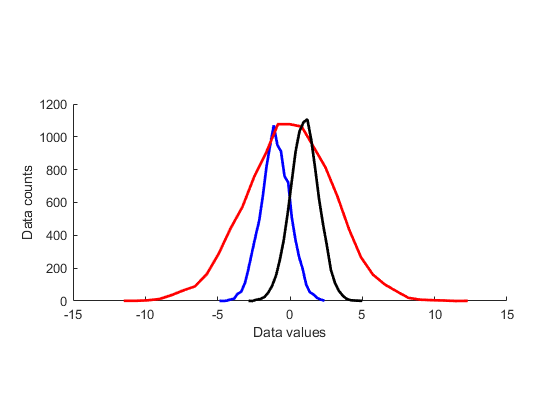

N = 10001; % number of data points
nbins = 30; % number of histogram bins

d1 = randn(N,1) - 1;
d2 = 3*randn(N,1);
d3 = randn(N,1) + 1;

% need their histograms
[y1,x1] = histcounts(d1,nbins);
x1 = (x1(1:end-1)+x1(2:end))/2;

[y2,x2] = histcounts(d2,nbins);
x2 = (x2(1:end-1)+x2(2:end))/2;

[y3,x3] = histcounts(d3,nbins);
x3 = (x3(1:end-1)+x3(2:end))/2;


% plot them
figure(1), clf
subplot(5,1,2:4), hold on

plot(x1,y1,'b','linew',2)
plot(x2,y2,'r','linew',2)
plot(x3,y3,'k','linew',2)

xlabel('Data values')
ylabel('Data counts')

## overlay the mean

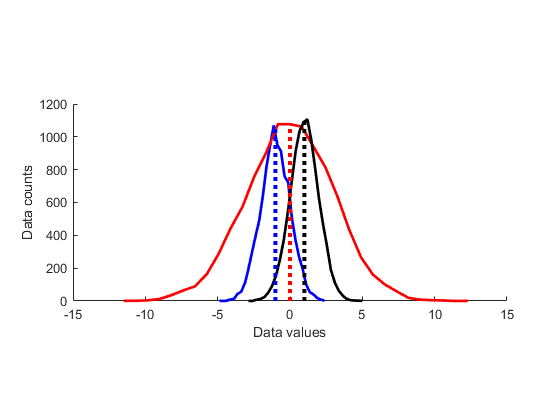

% compute the means
mean_d1 = sum(d1) / length(d1);
mean_d2 = mean(d2);
mean_d3 = mean(d3);

% plot them
plot([1 1]*mean_d1,[0 max(y1)],'b:','linew',3)
plot([1 1]*mean_d2,[0 max(y2)],'r:','linew',3)
plot([1 1]*mean_d3,[0 max(y3)],'k:','linew',3)

## standard deviation

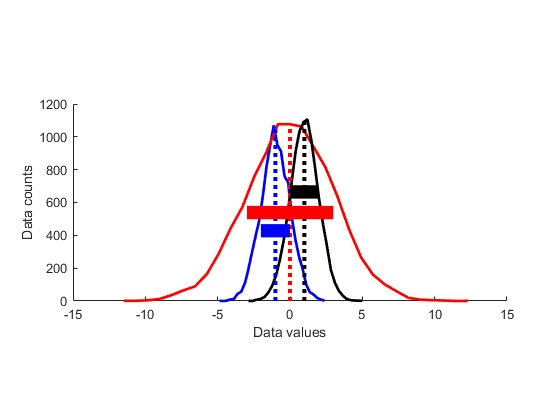

% initialize
stds = zeros(3,1);

% compute standard deviations in a weird loop
for i=1:3
    eval(sprintf('stds(%g) = std(d%g);',i,i))
end

% now plot on top
plot([mean_d1-stds(1) mean_d1+stds(1)],[.4 .4]*max(y1),'b','linew',10)
plot([mean_d2-stds(2) mean_d2+stds(2)],[.5 .5]*max(y2),'r','linew',10)
plot([mean_d3-stds(3) mean_d3+stds(3)],[.6 .6]*max(y3),'k','linew',10)

## different variance measures

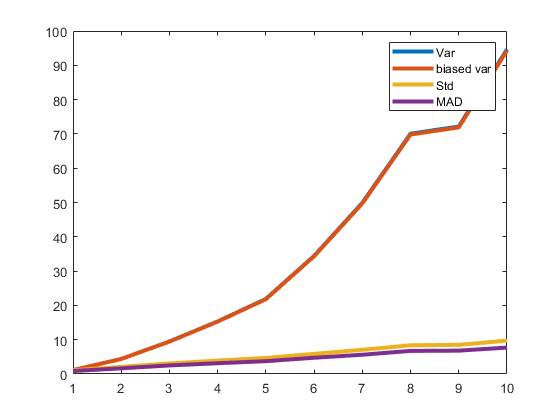

vars = 1:10;
N = 300;

varmeasures = zeros(4,length(vars));

for i=1:length(vars)
    
    % create data and mean-center
    data = randn(N,1) * vars(i);
    datacent = data - mean(data);
    
    % variance
    varmeasures(1,i) = sum(datacent.^2) / (N-1);
    
    % "biased" variance
    varmeasures(2,i) = sum(datacent.^2) / N;
    
    % standard deviation
    varmeasures(3,i) = sqrt( sum(datacent.^2) / (N-1) );
    
    % MAD (mean absolute difference)
    varmeasures(4,i) = sum(abs(datacent)) / (N-1);
end

% show them!
figure(2), clf
plot(vars,varmeasures,'linew',3)
legend({'Var';'biased var';'Std';'MAD'})

## Fano factor and coefficient of variation (CV)

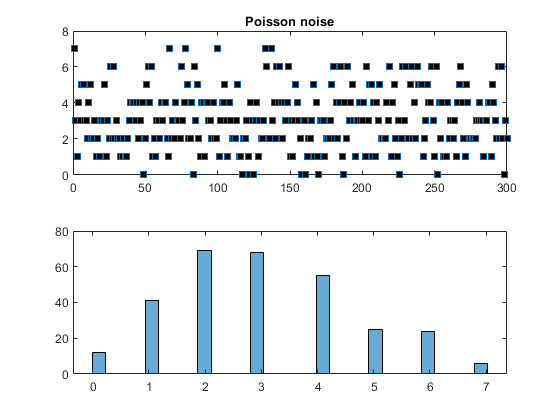

% need positive-valued data (why?)
data = poissrnd(3,300,1); % "Poisson noise"

figure(3), clf
subplot(211)
plot(data,'s','markerfacecolor','k')
title('Poisson noise')

subplot(212)
histogram(data,30)

## compute fano factor and CV for a range of lambda parameters

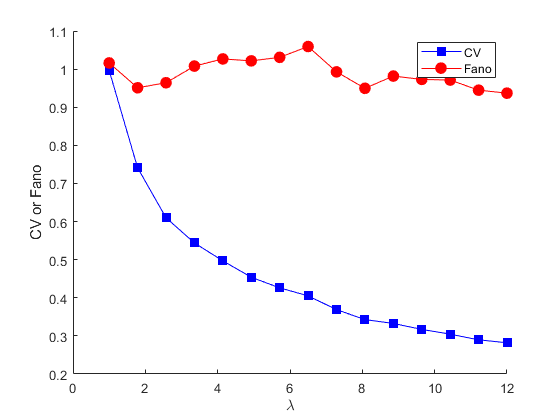

% list of parameters
lambdas = linspace(1,12,15);

% initialize output vectors
[cv,fano] = deal( zeros(length(lambdas),1) );

for li = 1:length(lambdas)
    
    % generate new data
    data = poissrnd(lambdas(li),1000,1);
    
    % compute the metrics
    cv(li) = std(data) / mean(data);
    fano(li) = var(data) / mean(data);
end

% and plot
figure(4), clf, hold on
plot(lambdas,cv,'bs-','markersize',8,'markerfacecolor','b')
plot(lambdas,fano,'ro-','markersize',8,'markerfacecolor','r')
legend({'CV';'Fano'})
xlabel('$\lambda$','Interpreter','latex')
ylabel('CV or Fano')

## done.